# **Two-story steel MRF in OpenSeesMatlab style**

Converted from an OpenSeesPy notebook [OpenSeesPy-Examples/Two Story Steel MRF (FGU).ipynb at master · AmirHosseinNamadchi/OpenSeesPy-Examples](https://github.com/AmirHosseinNamadchi/OpenSeesPy-Examples/blob/master/Two%20Story%20Steel%20MRF%20(FGU).ipynb)

The model uses:

* distributed-plasticity fiber columns;

* elastic beam elements;

* zeroLength rotational springs for beam plastic hinges;

* gravity, modal, pushover, and time-history analyses.

The ground-motion file: [acc_1.txt](../../utils/acc_1.txt).

In this notebook, a 2 story steel moment resisting frame is modeled. This is an OpenSeesPy simulation of TCL version of the model, presented by [*Fernando Gutiérrez Urzúa*](https://www.ucl.ac.uk/epicentre/fernando-gutierrez-urzua) in his [YouTube channel](https://www.youtube.com/user/lfgurzua). Some minor modifications are made by me in the python version. According to his, modeling assumptions are:

- Columns are modeled as distributed plasticity elements

- Beams are modeled as concentrated plasticity elements

- Plastic hinges are modeled as two nodes at the same coordinates, connected via a rotational spring.

The functions defined in this notebook are as follows:

- `W_section`: *Creates W-Section based on nominal dimension and generates fibers over it*

- `build_model`: *Builds the 2D Steel Moment resisting Frame Model*

- `run_gravity`: *Runs gravity analysis*

- `run_modal`: *Runs Modal analysis*

- `run_pushover`: *Runs Pushover analysis*

- `run_time_history`: *Runs Time history analysis*

- `reset_analysis`: *Resets the analysis by setting time to 0,removing the recorders and wiping the analysis.*

Please note that some functions use data obtained by running other functions. For example, in order to run Pushover analysis, some components of eigenvectors are needed that is obtained via `run_modal` function. It's highly recommended to watch Dr. Fernando Gutiérrez Urzúa videos for better understanding.

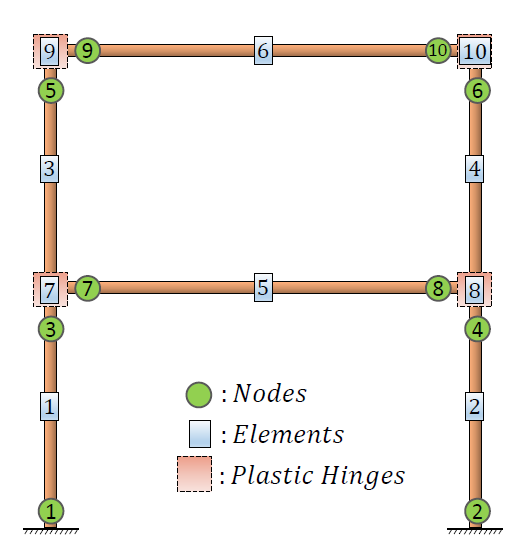

clear; clc; close all;

opsMAT = OpenSeesMatlab;
ops = opsMAT.opensees;
opsvis = opsMAT.vis;

outputDir = fullfile(pwd, 'output_data/FGU_2SSMRF_files');
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

data = build_model(ops, outputDir);

Model built successfully.


opsvis.polyscope.plotModel();

[OpenSeesMatlab] Backend: openGL3_glfw -- Loaded openGL version: 3.3.0 NVIDIA 610.74


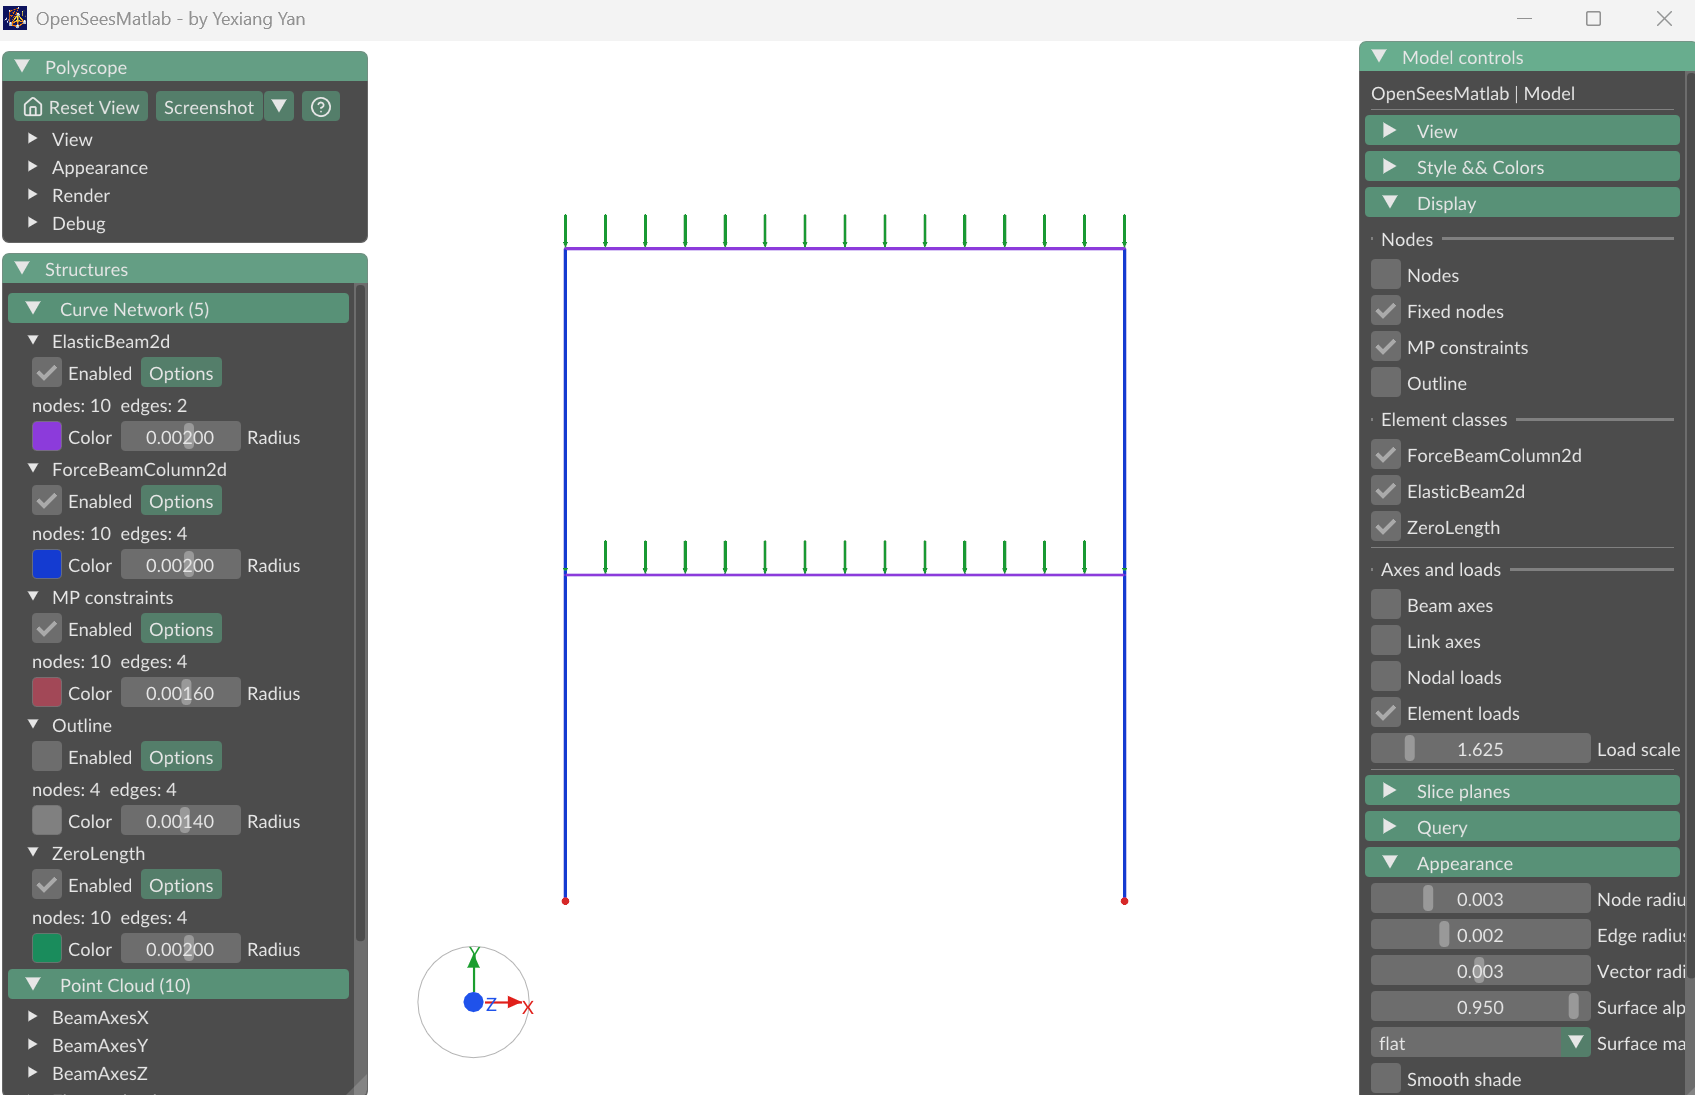

ops.wipe();

### Select analysis examples

runGravityExample     = true;
runModalExample       = true;
runPushoverExample    = true;
runTimeHistoryExample = true;

%% Gravity analysis only
if runGravityExample
    data = build_model(ops, outputDir);
    run_gravity(ops, outputDir, 10);
    reset_analysis(ops);
    ops.wipe();
end

Model built successfully.


Gravity analysis done.


### Modal analysis only

if runModalExample
    data = build_model(ops, outputDir);
    run_modal(ops, outputDir, 2);
    reset_analysis(ops);
    ops.wipe();
end

Model built successfully.


Modal analysis done.


### Pushover analysis

Model built successfully.


Modal analysis done.


Gravity analysis done.


Pushover analysis done in 0.71 seconds.


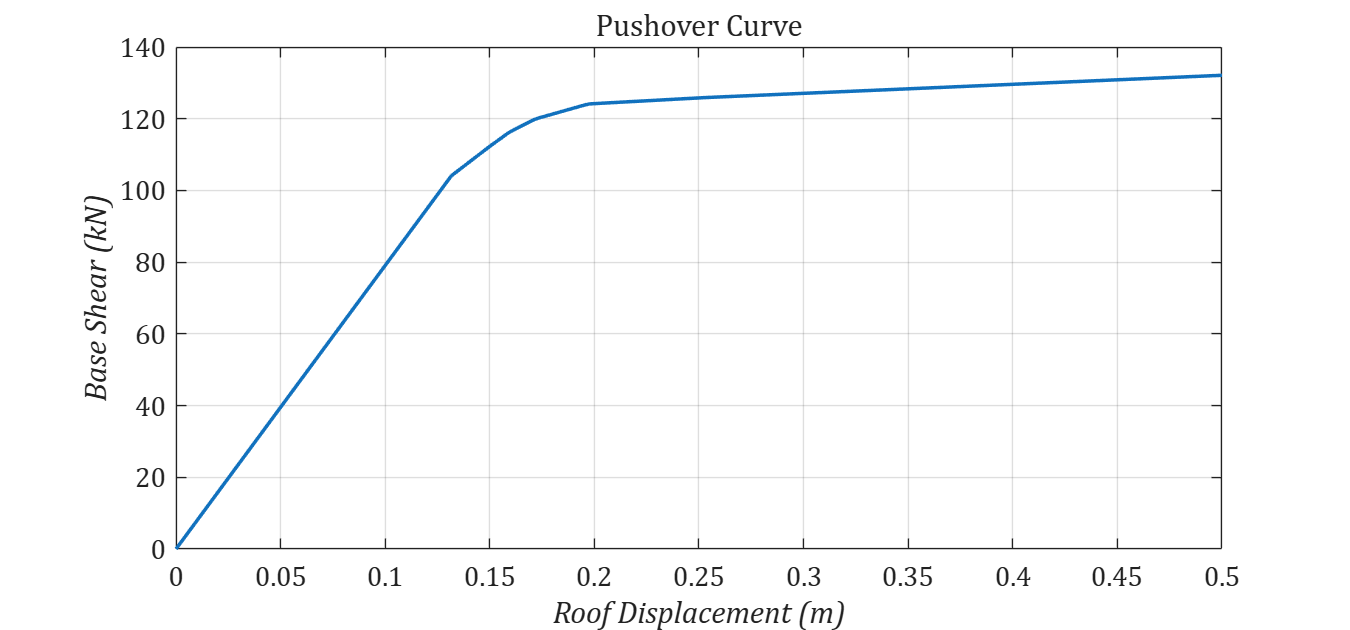

if runPushoverExample
    data = build_model(ops, outputDir);
    run_modal(ops, outputDir, 2);      % needed for the first-mode load pattern
    reset_analysis(ops);
    run_gravity(ops, outputDir, 10);
    reset_analysis(ops);
    run_pushover(ops, data, outputDir, 5000);
    plot_pushover(outputDir);
    ops.wipe();
end

### Time-history analysis

[acc_1.txt](../../utils/acc_1.txt)

Model built successfully.


Modal analysis done.


Gravity analysis done.


Running time-history analysis with lambda = 1.
Time-history analysis done in 14.63 seconds.


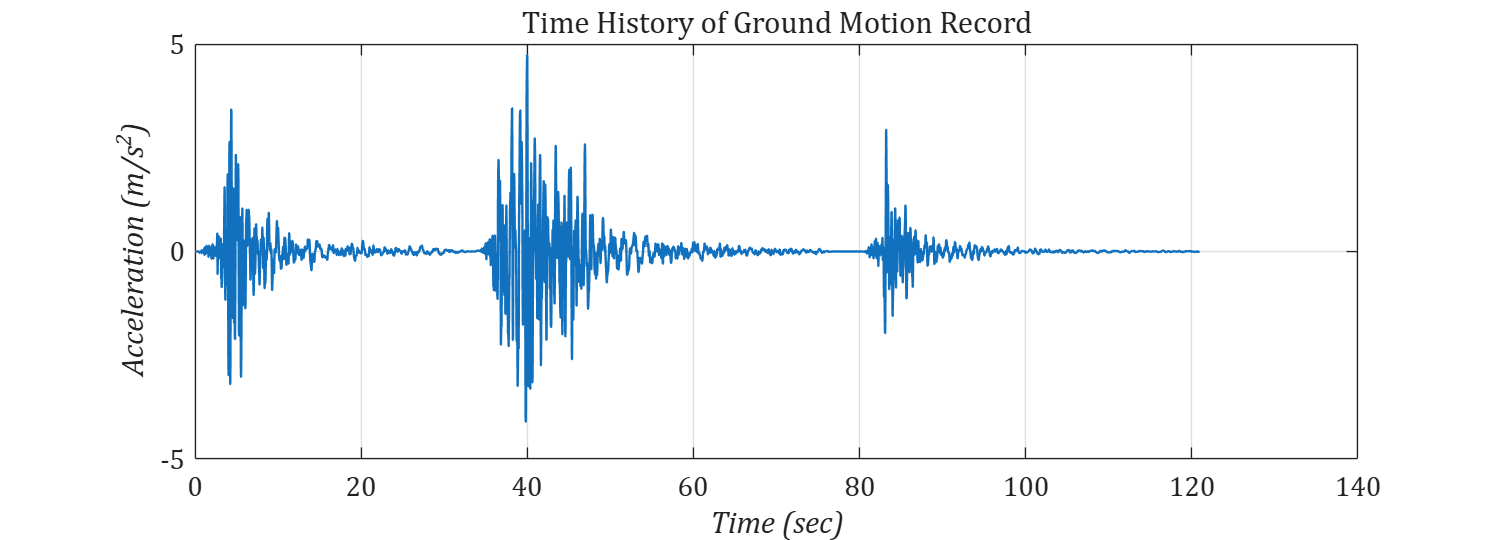

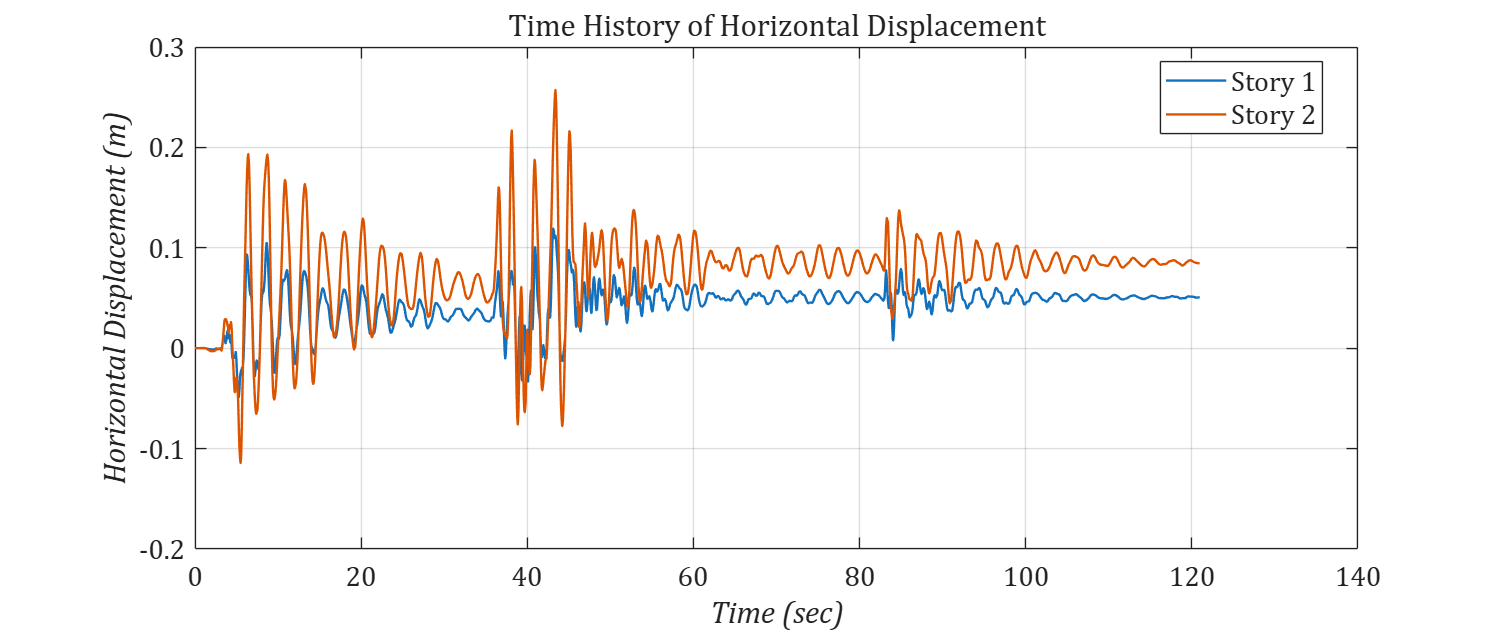

if runTimeHistoryExample
    data = build_model(ops, outputDir);
    run_modal(ops, outputDir, 2);      % needed for Rayleigh damping
    reset_analysis(ops);
    run_gravity(ops, outputDir, 10);
    reset_analysis(ops);
    run_time_history(ops, outputDir, 1, 1, 1.0, fullfile('utils/acc_1.txt'));
    plot_time_history(outputDir);
    ops.wipe();
end

### Local functions

#### W_section

function W_section(ops, sectionData, secTag, matTag, nfDw, nfTw, nfBf, nfTf)
%W_SECTION Create a 2D W-section fiber section.

    d  = sectionData.d;
    bf = sectionData.bf;
    tf = sectionData.tf;
    tw = sectionData.tw;

    dw = d - 2.0 * tf;

    y1 = -d  / 2.0;
    y2 = -dw / 2.0;
    y3 =  dw / 2.0;
    y4 =  d  / 2.0;

    z1 = -bf / 2.0;
    z2 = -tw / 2.0;
    z3 =  tw / 2.0;
    z4 =  bf / 2.0;

    ops.section('Fiber', secTag);

    % Bottom flange
    ops.patch('quad', matTag, nfBf, nfTf, ...
        y1, z4, y1, z1, y2, z1, y2, z4);

    % Web
    ops.patch('quad', matTag, nfTw, nfDw, ...
        y2, z3, y2, z2, y3, z2, y3, z3);

    % Top flange
    ops.patch('quad', matTag, nfBf, nfTf, ...
        y3, z4, y3, z1, y4, z1, y4, z4);
end

#### build_model

function data = build_model(ops, outputDir)
%BUILD_MODEL Build the two-story steel moment-resisting frame.

    %#ok<*NASGU>

    %% Units
    m   = 1.0;
    KN  = 1.0;
    sec = 1.0;

    mm  = 0.001 * m;
    cm  = 0.01  * m;
    ton = KN * sec^2 / m;
    g   = 9.81 * m / sec^2;

    ops.wipe();
    ops.model('basic', '-ndm', 2, '-ndf', 3);

    Lx = 6.0 * m;
    Ly = 3.5 * m;

    nodeCoords = [
        0.0, 0.0;
        Lx,  0.0;
        0.0, Ly;
        Lx,  Ly;
        0.0, 2.0 * Ly;
        Lx,  2.0 * Ly;
        0.0, Ly;
        Lx,  Ly;
        0.0, 2.0 * Ly;
        Lx,  2.0 * Ly];

    connectivity = [
        1,  3;
        2,  4;
        3,  5;
        4,  6;
        7,  8;
        9, 10;
        7,  3;
        8,  4;
        9,  5;
       10,  6];

    nel = size(connectivity, 1);

    allBeams  = [5, 6];
    allCols   = [1, 2, 3, 4];
    allHinges = [7, 8, 9, 10];

    %% Materials
    matS355.ID     = 'Steel01';
    matS355.matTag = 1;
    matS355.Fy     = 3.55e5 * KN / m^2;
    matS355.E0     = 2.10e8 * KN / m^2;
    matS355.b      = 0.01;

    matLignos.ID             = 'Bilin';
    matLignos.matTag         = 2;
    matLignos.K0             = 64033.2 * KN / m;
    matLignos.as_Plus        = 0.00203545752454409;
    matLignos.as_Neg         = 0.00203545752454409;
    matLignos.My_Plus        = 101.175 * KN * m;
    matLignos.My_Neg         = -101.175 * KN * m;
    matLignos.Lamda_S        = 1.50476106091578;
    matLignos.Lamda_C        = 1.50476106091578;
    matLignos.Lamda_A        = 1.50476106091578;
    matLignos.Lamda_K        = 1.50476106091578;
    matLignos.c_S            = 1;
    matLignos.c_C            = 1;
    matLignos.c_A            = 1;
    matLignos.c_K            = 1;
    matLignos.theta_p_Plus   = 0.0853883552651735;
    matLignos.theta_p_Neg    = 0.0853883552651735;
    matLignos.theta_pc_Plus  = 0.234610805942179;
    matLignos.theta_pc_Neg   = 0.234610805942179;
    matLignos.Res_Pos        = 0.4;
    matLignos.Res_Neg        = 0.4;
    matLignos.theta_u_Plus   = 0.4;
    matLignos.theta_u_Neg    = 0.4;
    matLignos.D_Plus         = 1;
    matLignos.D_Neg          = 1;

    %% Sections
    sections.IPE220.d  = 220.0 * mm;
    sections.IPE220.tw = 5.9   * mm;
    sections.IPE220.bf = 110.0 * mm;
    sections.IPE220.tf = 9.2   * mm;
    sections.IPE220.A  = 33.4  * cm^2;
    sections.IPE220.I1 = 2772.0 * cm^4;
    sections.IPE220.I2 = 205.0  * cm^4;

    sections.HE180B.d  = 180.0 * mm;
    sections.HE180B.tw = 8.5   * mm;
    sections.HE180B.bf = 180.0 * mm;
    sections.HE180B.tf = 14.0  * mm;
    sections.HE180B.A  = 65.3  * cm^2;
    sections.HE180B.I1 = 3830.0 * cm^4;
    sections.HE180B.I2 = 1360.0 * cm^4;

    %% Nodes
    for i = 1:size(nodeCoords, 1)
        ops.node(i, nodeCoords(i, 1), nodeCoords(i, 2));
    end

    %% Boundary conditions
    ops.fix(1, 1, 1, 1);
    ops.fix(2, 1, 1, 1);

    % Tie translations only at duplicated hinge nodes.
    ops.equalDOF(3, 7, 1, 2);
    ops.equalDOF(4, 8, 1, 2);
    ops.equalDOF(5, 9, 1, 2);
    ops.equalDOF(6, 10, 1, 2);

    %% Materials
    ops.uniaxialMaterial(matS355.ID, matS355.matTag, ...
        matS355.Fy, matS355.E0, matS355.b);

    ops.uniaxialMaterial(matLignos.ID, matLignos.matTag, ...
        matLignos.K0, ...
        matLignos.as_Plus, matLignos.as_Neg, ...
        matLignos.My_Plus, matLignos.My_Neg, ...
        matLignos.Lamda_S, matLignos.Lamda_C, matLignos.Lamda_A, matLignos.Lamda_K, ...
        matLignos.c_S, matLignos.c_C, matLignos.c_A, matLignos.c_K, ...
        matLignos.theta_p_Plus, matLignos.theta_p_Neg, ...
        matLignos.theta_pc_Plus, matLignos.theta_pc_Neg, ...
        matLignos.Res_Pos, matLignos.Res_Neg, ...
        matLignos.theta_u_Plus, matLignos.theta_u_Neg, ...
        matLignos.D_Plus, matLignos.D_Neg);

    %% Fiber section for columns
    W_section(ops, sections.HE180B, 1, matS355.matTag, 4, 2, 4, 2);

    %% Transformation
    ops.geomTransf('PDelta', 1);

    %% Elements
    for e = allBeams
        ni = connectivity(e, 1);
        nj = connectivity(e, 2);
        ops.element('elasticBeamColumn', e, ni, nj, ...
            sections.IPE220.A, matS355.E0, sections.IPE220.I1, 1);
    end

    for e = allCols
        ni = connectivity(e, 1);
        nj = connectivity(e, 2);
        ops.element('nonlinearBeamColumn', e, ni, nj, 4, 1, 1);
    end

    hingeRotDir = 6;
    for e = allHinges
        ni = connectivity(e, 1);
        nj = connectivity(e, 2);
        ops.element('zeroLength', e, ni, nj, ...
            '-mat', matLignos.matTag, '-dir', hingeRotDir);
    end

    %% Gravity loads and floor masses
    DL = 20.0 * KN / m;
    CL = 50.0 * KN;
    m1 = 75.0 * ton;

    loadedNodes = [3, 4, 5, 6];
    loadedElems = [5, 6];

    ops.timeSeries('Linear', 1, '-factor', 1.0);
    ops.pattern('Plain', 1, 1);

    for n = loadedNodes
        ops.load(n, 0.0, -CL, 0.0);
    end

    ops.eleLoad('-ele', loadedElems(1), loadedElems(2), ...
        '-type', '-beamUniform', -DL);

    for n = loadedNodes
        ops.mass(n, 0.5 * m1, 0.0, 0.0);
    end

    data.m1           = m1;
    data.outputDir    = outputDir;
    data.connectivity = connectivity;
    data.allBeams     = allBeams;
    data.allCols      = allCols;
    data.allHinges    = allHinges;
    data.sections     = sections;
    data.matS355      = matS355;
    data.matLignos    = matLignos;

    fprintf('Model built successfully.\n');
end

#### run_gravity

function run_gravity(ops, outputDir, steps)
%RUN_GRAVITY Run gravity analysis.

    if nargin < 3
        steps = 10;
    end

    ops.initialize();

    ops.recorder('Node', '-file', fullfile(outputDir, 'Gravity_Reactions.out'), ...
        '-time', '-node', 1, 2, '-dof', 1, 2, 3, 'reaction');

    ops.constraints('Plain');
    ops.numberer('RCM');
    ops.system('ProfileSPD');
    ops.test('NormDispIncr', 1.0e-6, 100, 0, 2);
    ops.algorithm('Newton');
    ops.integrator('LoadControl', 0.1);
    ops.analysis('Static');

    ops.record();
    ok = ops.analyze(steps);

    if ok == 0
        fprintf('Gravity analysis done.\n');
    else
        fprintf('Gravity analysis failed with code %d.\n', ok);
    end
end

#### run_modal

function run_modal(ops, outputDir, nEvs)
%RUN_MODAL Run modal analysis and save eigen information.

    if nargin < 3
        nEvs = 2;
    end

    ops.initialize();

    ops.recorder('Node', '-file', fullfile(outputDir, 'ModalAnalysis_Node_EigenVectors_EigenVec1.out'), ...
        '-node', 1, 3, 5, '-dof', 1, 'eigen 1');
    ops.recorder('Node', '-file', fullfile(outputDir, 'ModalAnalysis_Node_EigenVectors_EigenVec2.out'), ...
        '-node', 1, 3, 5, '-dof', 1, 'eigen 2');

    ops.constraints('Transformation');
    ops.numberer('Plain');
    ops.system('BandGen');
    ops.test('NormDispIncr', 1.0e-12, 25, 0, 2);
    ops.algorithm('Newton');
    ops.integrator('Newmark', 0.5, 0.25);
    ops.analysis('Transient');

    lambdaVals = ops.eigen(nEvs);
    lambdaVals = lambdaVals(:);

    eigFile = fullfile(outputDir, 'ModalAnalysis_Node_EigenVectors_EigenVal.out');
    fid = fopen(eigFile, 'w');
    fprintf(fid, 'lambda omega period frequency\n');
    for i = 1:numel(lambdaVals)
        lam = lambdaVals(i);
        omega = sqrt(lam);
        period = 2.0 * pi / omega;
        frequency = omega / (2.0 * pi);
        fprintf(fid, '%2.6e %2.6e %2.6e %2.6e\n', lam, omega, period, frequency);
    end
    fclose(fid);

    ops.record();
    fprintf('Modal analysis done.\n');
end

#### run_pushover

function run_pushover(ops, data, outputDir, steps)
%RUN_PUSHOVER Run pushover analysis using the first-mode load pattern.

    if nargin < 4
        steps = 5000;
    end

    ops.recorder('Node', '-file', fullfile(outputDir, 'Pushover_Horizontal_Reactions.out'), ...
        '-time', '-node', 1, 2, '-dof', 1, 'reaction');
    ops.recorder('Node', '-file', fullfile(outputDir, 'Pushover_Story_Displacement.out'), ...
        '-time', '-node', 3, 5, '-dof', 1, 'disp');

    ops.recorder('Element', '-file', fullfile(outputDir, 'Pushover_BeamHinge_GlbForc.out'), ...
        '-time', '-ele', 7, 8, 9, 10, 'force');
    ops.recorder('Element', '-file', fullfile(outputDir, 'Pushover_BeamHinge_Deformation.out'), ...
        '-time', '-eleRange', 7, 10, 'deformation');
    ops.recorder('Element', '-file', fullfile(outputDir, 'Pushover_Column_GlbForc.out'), ...
        '-time', '-eleRange', 1, 4, 'globalForce');
    ops.recorder('Element', '-file', fullfile(outputDir, 'Pushover_Column_ChordRot.out'), ...
        '-time', '-ele', 1, 2, 3, 4, 'chordRotation');

    tic;

    phiFile = fullfile(outputDir, 'ModalAnalysis_Node_EigenVectors_EigenVec1.out');
    phi = abs(readmatrix(phiFile, 'FileType', 'text'));
    phi = phi(:);

    % The file records nodes [1, 3, 5]. Use entries for floors 1 and 2.
    ops.pattern('Plain', 2, 1);
    for n = [3, 4]
        ops.load(n, data.m1 * phi(2), 0.0, 0.0);
    end
    for n = [5, 6]
        ops.load(n, data.m1 * phi(3), 0.0, 0.0);
    end

    stepSize = 1.0e-4;

    ops.constraints('Transformation');
    ops.numberer('RCM');
    ops.system('BandGen');
    ops.test('NormDispIncr', 1.0e-6, 100);
    ops.algorithm('NewtonLineSearch', '-type', 'Bisection', ...
        '-tol', 0.8, '-maxIter', 1000, '-minEta', 0.1, '-maxEta', 10.0);
    ops.integrator('DisplacementControl', 5, 1, stepSize);
    ops.analysis('Static');

    ops.record();
    ok = ops.analyze(steps);

    elapsedTime = toc;
    if ok == 0
        fprintf('Pushover analysis done in %.2f seconds.\n', elapsedTime);
    else
        fprintf('Pushover analysis failed with code %d after %.2f seconds.\n', ok, elapsedTime);
    end
end

#### run_time_history

function run_time_history(ops, outputDir, gMotionId, scalingId, lambdaScale, accFile)
%RUN_TIME_HISTORY Run nonlinear time-history analysis.

    if nargin < 3 || isempty(gMotionId)
        gMotionId = 1;
    end
    if nargin < 4 || isempty(scalingId)
        scalingId = 1;
    end
    if nargin < 5 || isempty(lambdaScale)
        lambdaScale = 1.0;
    end
    if nargin < 6 || isempty(accFile)
        accFile = fullfile(outputDir, 'acc_1.txt');
    end

    ops.recorder('Node', '-file', fullfile(outputDir, sprintf('TimeHistory_Horizontal_Reactions.%d.%d.out', gMotionId, scalingId)), ...
        '-time', '-node', 1, 2, '-dof', 1, 'reaction');
    ops.recorder('Node', '-file', fullfile(outputDir, sprintf('TimeHistory_Story_Displacement.%d.%d.out', gMotionId, scalingId)), ...
        '-time', '-node', 3, 5, '-dof', 1, 'disp');

    ops.recorder('Element', '-file', fullfile(outputDir, sprintf('TimeHistory_BeamHinge_GlbForc.%d.%d.out', gMotionId, scalingId)), ...
        '-time', '-ele', 7, 8, 9, 10, 'force');
    ops.recorder('Element', '-file', fullfile(outputDir, sprintf('TimeHistory_BeamHinge_Deformation.%d.%d.out', gMotionId, scalingId)), ...
        '-time', '-eleRange', 7, 10, 'deformation');
    ops.recorder('Element', '-file', fullfile(outputDir, sprintf('TimeHistory_Column_GlbForc.%d.%d.out', gMotionId, scalingId)), ...
        '-time', '-eleRange', 1, 4, 'globalForce');
    ops.recorder('Element', '-file', fullfile(outputDir, sprintf('TimeHistory_Column_ChordRot.%d.%d.out', gMotionId, scalingId)), ...
        '-time', '-ele', 1, 2, 3, 4, 'chordRotation');

    %% Rayleigh damping from modal results
    eigTable = readmatrix(fullfile(outputDir, 'ModalAnalysis_Node_EigenVectors_EigenVal.out'), ...
        'FileType', 'text', 'NumHeaderLines', 1);
    omega = eigTable(:, 2);

    xi = [0.03; 0.03];
    coefMat = [omega(2), -omega(1); -1.0 / omega(2), 1.0 / omega(1)];
    dampingCoef = 2.0 * ((omega(1) * omega(2)) / (omega(2)^2 - omega(1)^2)) * coefMat * xi;
    aR = dampingCoef(1);
    bR = dampingCoef(2);

    %% Ground motion
    if ~exist(accFile, 'file')
        error('Ground-motion file not found: %s', accFile);
    end

    accelerogram = readmatrix(accFile, 'FileType', 'text');
    accelerogram = accelerogram(:);

    dt = 0.02;
    nSteps = numel(accelerogram);
    tol = 1.0e-6;
    maxIter = 5000;

    ops.test('NormDispIncr', tol, maxIter, 0, 0);
    ops.numberer('RCM');
    ops.system('BandGen');

    % Use a temporary file rather than a long '-values' list
    scaledAccFile = fullfile(outputDir, sprintf('scaled_acc_%d_%d.txt', gMotionId, scalingId));
    writematrix(accelerogram, scaledAccFile, 'Delimiter', ' ');

    ops.timeSeries('Path', 2, '-dt', dt, '-filePath', scaledAccFile, '-factor', lambdaScale);
    ops.pattern('UniformExcitation', 3, 1, '-accel', 2);

    ops.constraints('Transformation');
    ops.integrator('Newmark', 0.5, 0.25);
    ops.rayleigh(aR, bR, 0.0, 0.0);
    ops.algorithm('NewtonLineSearch', '-type', 'Bisection', ...
        '-tol', 0.8, '-maxIter', 100, '-minEta', 0.1, '-maxEta', 10.0);
    ops.analysis('Transient');

    fprintf('Running time-history analysis with lambda = %.4g.\n', lambdaScale);
    tic;

    t = 0.0;
    ok = 0;
    finalTime = ops.getTime() + nSteps * dt;
    dtAnalysis = 0.1 * dt;

    while ok == 0 && t <= finalTime
        ok = ops.analyze(1, dtAnalysis);
        t = ops.getTime();
    end

    elapsedTime = toc;
    if ok == 0
        fprintf('Time-history analysis done in %.2f seconds.\n', elapsedTime);
    else
        fprintf('Time-history analysis failed with code %d after %.2f seconds.\n', ok, elapsedTime);
    end
end

#### Plot functions

function reset_analysis(ops)
%RESET_ANALYSIS Reset domain time, loads, recorders, and analysis objects.

    ops.setTime(0.0);
    ops.loadConst();
    ops.remove('recorders');
    ops.wipeAnalysis();
end

function plot_pushover(outputDir)
%PLOT_PUSHOVER Plot base shear versus roof displacement.

    reactFile = fullfile(outputDir, 'Pushover_Horizontal_Reactions.out');
    dispFile  = fullfile(outputDir, 'Pushover_Story_Displacement.out');

    if ~exist(reactFile, 'file') || ~exist(dispFile, 'file')
        warning('Pushover output files not found. Skipping pushover plot.');
        return;
    end

    poverReact = readmatrix(reactFile, 'FileType', 'text');
    poverDisp  = readmatrix(dispFile,  'FileType', 'text');

    roofDisp  = poverDisp(:, 3);
    baseShear = -(poverReact(:, 2) + poverReact(:, 3));

    figure('Color', 'w', 'Position', [100, 100, 900, 420]);
    plot(roofDisp, baseShear, 'LineWidth', 1.75);
    xlabel('Roof Displacement (m)', 'FontName', 'Cambria', 'FontSize', 14, 'FontAngle', 'italic');
    ylabel('Base Shear (kN)', 'FontName', 'Cambria', 'FontSize', 14, 'FontAngle', 'italic');
    title('Pushover Curve', 'FontName', 'Cambria', 'FontSize', 16, 'FontWeight', 'normal');
    grid on; box on;
    set(gca, 'FontName', 'Cambria', 'FontSize', 14);
end

function plot_time_history(outputDir)
%PLOT_TIME_HISTORY Plot ground motion and story displacement histories.

    accFile  = fullfile('utils/acc_1.txt');
    dispFile = fullfile(outputDir, 'TimeHistory_Story_Displacement.1.1.out');

    if exist(accFile, 'file')
        gm = readmatrix(accFile, 'FileType', 'text');
        gm = gm(:);
        dt = 0.02;
        t = (0:numel(gm)-1).' * dt;

        figure('Color', 'w', 'Position', [100, 100, 1000, 360]);
        plot(t, gm, 'LineWidth', 1.2);
        xlabel('Time (sec)', 'FontName', 'Cambria', 'FontSize', 14, 'FontAngle', 'italic');
        ylabel('Acceleration (m/s^2)', 'FontName', 'Cambria', 'FontSize', 14, 'FontAngle', 'italic');
        title('Time History of Ground Motion Record', 'FontName', 'Cambria', 'FontSize', 16, 'FontWeight', 'normal');
        grid on; box on;
        set(gca, 'FontName', 'Cambria', 'FontSize', 14);
    else
        warning('Ground-motion file not found. Skipping ground-motion plot.');
    end

    if exist(dispFile, 'file')
        storyDisp = readmatrix(dispFile, 'FileType', 'text');

        figure('Color', 'w', 'Position', [100, 100, 1000, 420]);
        plot(storyDisp(:, 1), storyDisp(:, 2), 'LineWidth', 1.2); hold on;
        plot(storyDisp(:, 1), storyDisp(:, 3), 'LineWidth', 1.2);
        xlabel('Time (sec)', 'FontName', 'Cambria', 'FontSize', 14, 'FontAngle', 'italic');
        ylabel('Horizontal Displacement (m)', 'FontName', 'Cambria', 'FontSize', 14, 'FontAngle', 'italic');
        title('Time History of Horizontal Displacement', 'FontName', 'Cambria', 'FontSize', 16, 'FontWeight', 'normal');
        legend({'Story 1', 'Story 2'}, 'FontName', 'Cambria', 'FontSize', 14, 'Location', 'best');
        grid on; box on;
        set(gca, 'FontName', 'Cambria', 'FontSize', 14);
    else
        warning('Story displacement output file not found. Skipping story-displacement plot.');
    end
end
